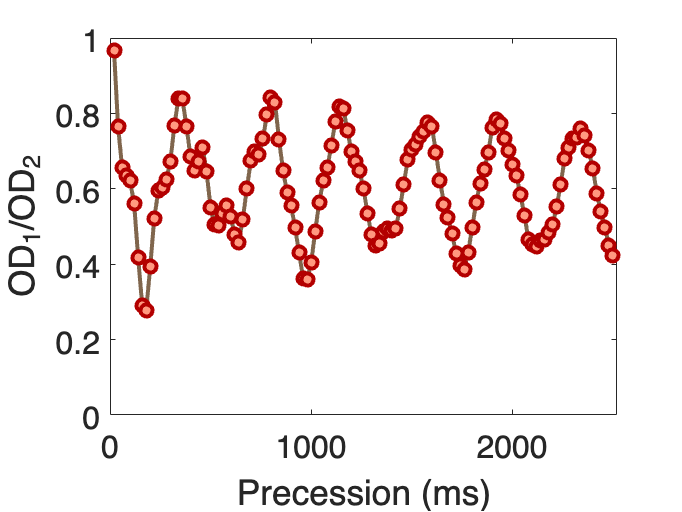

clear variables;
close all
load("Expt_Simulation/average.mat");

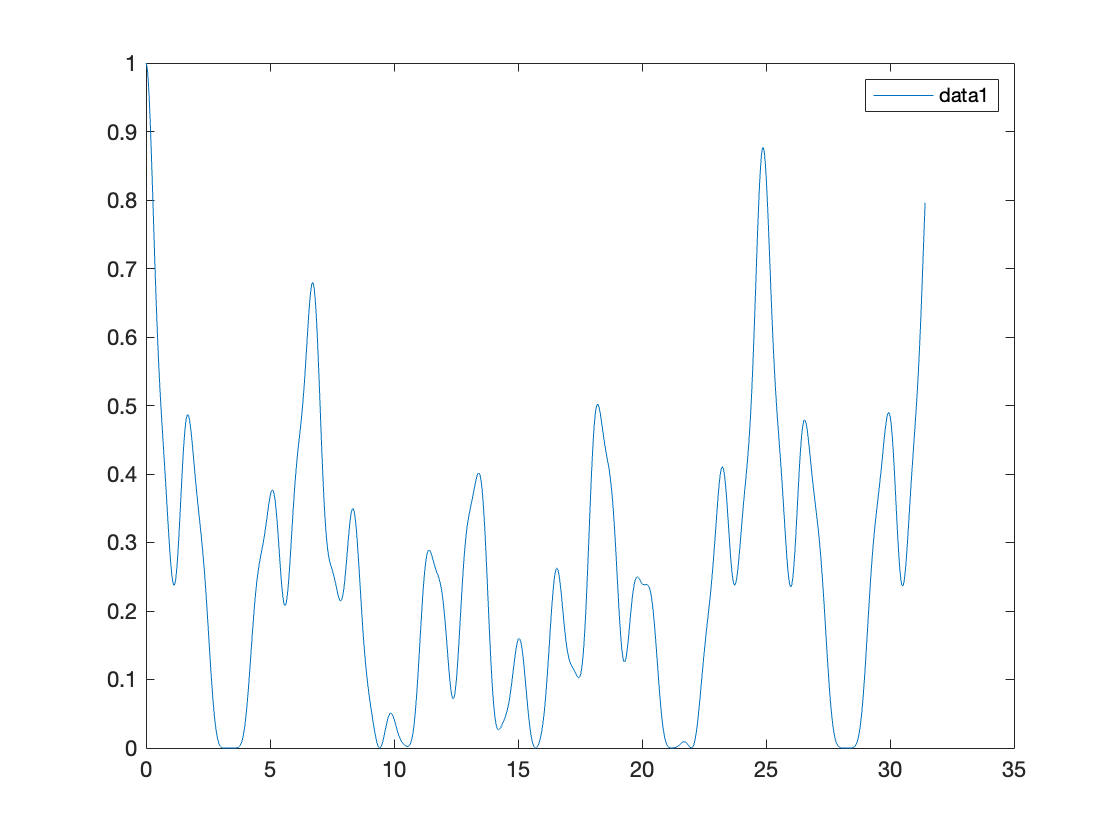

sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
initial=transpose([1 0 0 0 0 0]);
%initial=spin_coherent(pi/2,pi/2);
timelist=[0:0.01:10].*pi;

%ham=1*sigmax+0.43*sigmax^2+0*sigmay^2;
ham=sigmax+0.89*sigmax^2;
for i=1:length(timelist)
    time=timelist(i);
    finalstate(i,:)=ham_evolve(ham,initial,time);
end

figure;
for j=1:1
    plot(timelist,abs(finalstate(:,j)).^2,'-');
    hold on;
end
ylim([0 1]);
legend;
set(gcf,'visible','on')


phase=(abs(finalstate(:,1)).^2-abs(finalstate(:,6)).^2)...
    ./(abs(finalstate(:,1)).^2+abs(finalstate(:,6)).^2);
%figure;
%plot(timelist,phase);

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end
function state=spin_coherent(theta,phi)
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
polar=[1 0 0 0 0 0]';
state1=ham_evolve(sigmay,polar,theta);
state=ham_evolve(sigmaz,state1,phi);
end
